# Creation and simulation of personalized microbiota models trough metagenomic data integration

## Author: Federico Baldini, Molecular Systems Physiology Group, University of Luxembourg.

## INTRODUCTION

This tutorial shows the steps that MgPipe automatically performs to create and simulate personalized microbiota models trough metagenomic data integration.

The pipeline is divided in 3 parts:

- **[PART 1]** Analysis of individuals' specific microbes abundances is computed. Individuals? metabolic diversity in relation to microbiota size and disease presence as well as Classical multidimensional scaling (PCoA) on individuals' reaction repertoire are examples.

- **[PART 2]**: 1 Constructing a global metabolic model (setup) containing all the microbes listed in the study. 2 Building individuals' specific models integrating abundance data retrieved from metagenomics. For each organism, reactions are coupled to their objective function. 

- **[PART 3]** A specific range of growth is imposed for each microbiota model and Simulations under specific diet regimes are carried. Set of standard analysis to apply to the personalized models. PCA of computed MNPCs of individuals as for example.

## USAGE

Normally, once provided all the input variables in the driver (StartMgPipe), the only action required is to run the driver itself. However, for the purposes of this tutorial, we will disable the autorun functionality and compute each section manually. 

## DRIVER

This file has to be modified from the user in order to launch the pipeline and to define inputs and outputs files and locations. 

We first set the paths to input and output files

% path to microbiota models
modPath='YOUR_PATH_TO_AGORA\';
% path to where the Microbiome Modeling Toolbox is located
toolboxPath='YOUR_PATH_TO_Microbiome_Modeling_Toolbox\'

toolboxPath = YOUR_PATH_TO_Microbiome_Modeling_Toolbox\

% % path where to save results
resPath='YOUR PATH TO RESULT FOLDER\' ;
% path to and name of the file with dietary information. Here, 
% we will use an "Average European" diet that is located in the 
% DietImplementation folder.

modPath = /Users/almut.heinken/Documents/Unconstrained/mat/

toolboxPath = /Users/almut.heinken/Documents/GitHub/Microbiome_Toolbox/

resPath = /Users/almut.heinken/Documents/test/

dietFilePath=strcat(toolboxPath,'DietImplementation/AverageEuropeanDiet');

Then we set the path and the name of the file from which to load the abundances. For this tutorial, in order to reduce the time of computations, we will use a reduced version of the example file (normCoverageReduced.csv) provided in the folder Resources: only 4 individuals and 30 strains will be considered. Plese note that abundances are normalized to a total sum of one. 

abunFilePath=strcat(toolboxPath,'Resources/normCoverageReduced.csv');

Next inputs will define:

- name of objective function of organisms

- name of diet to use

- format to use to save images

- solver (and interface) to use

- number of cores to use for the pipeline execution 

- if to enable automatic detection and correction of possible bugs

- if to enable compatibility mode 

- if health status for individuals is provided 

- if to simulate also a rich diet

- if if to use an external solver and save models with diet

- the type of FVA function to use to solve 

The following setting should work for almost any system, but please check carefully to be sure these options are valid for you. A more detailed description of these variables is available in the documentation. 

The same inputs need to be set in the driver file StartMgPipe when running MgPipe

outside of this tutorial.

% name of objective function of organisms
objre={'EX_biomass(e)'};
% the output is vectorized picture, change to '-dpng' for .png
figForm = '-depsc';
% which solver (and interface) to use

## Where is the solver variable used? I can't find that anywhere

andthe pipeline crashed because the solver was not set!-Almut %%%%%

solver = 'tomlab_cplex'

solver = tomlab_cplex

% number of cores dedicated for parallelization
numWorkers = 3;
% autofix for names mismatch
autoFix = 1 

autoFix = 1

% if outputs in open formats should be produced for each section (1=T)
compMod = 0;
% if documentations on patient health status is provided (0 not 1 yes)
patStat = 0; 
% to enable also rich diet simulations 
rDiet = 0; 
% Add description-Almut
extSolve = 0; 
% Add description-Almut
fvaType = 1; 
% Additionally we will tourn off the autorun to be able to manually execute each part of the pipeline.
autorun=0; 
if autorun==1
    if numWorkers >= 2
        poolobj=gcp('nocreate');
        if isempty(poolobj)
            parpool(numWorkers)
        end
    end
    disp('Well done! Pipeline successfully activated and running!')
    MgPipe
else
    if numWorkers >= 2
        poolobj=gcp('nocreate');
        if isempty(poolobj)
            parpool(numWorkers)
        end
    end
    warning('autorun function was disabled. You are now running in manual / debug mode. If this is not what you wanted, change back to ?autorun?=1. Please note that the usage of manual mode is strongly discouraged and should be used only for debugging purposes.')
    edit('MgPipe.m')
end

if compMod == 1
    warning('compatibility mode activated. Output will also be saved in .csv / .sbml format. Time of computations will be affected.')    
else
    warning('pipeline output will be saved in .mat format. Please enable compomod option if you wish to activate compatibility mode.')
end


if numWorkers<2
   warning('apparently you disabled parallel mode to enable sequential one. Computations might become very slow. Please modify numWorkers option.')
end
if patStat==0
    disp('Individuals health status not declared. Analysis will ignore that.')
end

Individuals health status not declared. Analysis will ignore that.


## PIPELINE: [PART 1]

The number of organisms, their names, the number of samples and their identifiers are automatically detected from the input file. 

[patNumb,sampName,strains]=getIndividualSizeName(abunFilePath)

patNumb = 4

sampName =     'SRS011061'
    'SRS012902'
    'SRS011134'
    'SRS054956'


strains =     'Bacteroides_cellulosilyticus_DSM_14838'
    'Parabacteroides_merdae_ATCC_43184'
    'Bacteroides_vulgatus_ATCC_8482'
    'Alistipes_putredinis_DSM_17216'
    'Bacteroides_sp_4_3_47FAA'
    'Bacteroides_caccae_ATCC_43185'
    'Burkholderiales_bacterium_1_1_47'
    'Bacteroides_sp_20_3'
    'Bacteroides_ovatus_ATCC_8483'
    'Bacteroides_sp_2_1_33B'
    'Bacteroides_intestinalis_341_DSM_17393'
    'Bacteroides_sp_3_1_19'
    'Parabacteroides_sp_D13'
    'Parabacteroides_distasonis_ATCC_8503'
    'Bacteroides_sp_2_1_7'
    'Faecalibacterium_prausnitzii_M21_2'
    'Bacteroides_sp_9_1_42FAA'
    'Bacteroides_sp_2_2_4'
    'Bacteroides_plebeius_M12_DSM_17135'
    'Bacteroides_sp_3_1_23'
    'Bacteroides_ovatus_SD_CMC_3f'
    'Faecalibacterium_prausnitzii_L2_6'
    'Parabacteroides_johnsonii_DSM_18315'
    'Bacteroides_coprocola_M16_DSM_17136'
    'Roseburia_intestinalis_L1_82'
    'Bacteroides_sp_1_1_6'
    'Bacteroides_eggerthii_1_2_48FAA'
    'Bacteroides_dorei_DSM_17855'
  

Now we detect from the content of the results folder if PART1 was already computed: if the associated file is already present in the results folder its execution is skipped else its execution starts

[mapP]=detectOutput(resPath,'mapInfo.mat');

if ~isempty(mapP)
    s= 'mapping file found: loading from resPath and skipping [PART1] analysis';
    disp(s)
    load(strcat(resPath,'mapInfo.mat'))
end

mapping file found: loading from resPath and skipping [PART1] analysis


In case PART 1 was not computed we will compute it now. We will first load the models and create a cell array containing them. This cell array will be used as input by many functions in the pipeline. Any possible constraint from each model reactions will be removed. Moreover we will run and subsequentially plot the results of some analysis that are computed. The main outputs are:

- **Metabolic diversity** The number of mapped organisms for each individual compared to the total number of unique reactions (extrapolated by the number of reactions of each organism) 

- **Classical multidimensional scaling of each individual reactions repertoire** 

reac =     '12DGR180ti'
    '12PPDt'
    '1P4H2CBXLAH'
    '23DHMPO'
    '23PDE2'
    '23PDE4'
    '23PDE7'
    '23PDE9'
    '26DAPLLAT'
    '26DAPt2r'
    '2AHBUTI'
    '2DHPL'
    '2HBO'
    '2HYOXPLACt2r'
    '2INSD'
    '2MBCOATA'
    '2MMALD'
    '2MMALD2'
    '2OBUTt2r'
    '2OMMBOX'
    '2OMPHH'
    '34DHOXPEGOX'
    '36DAHXI'
    '3ABUTCOAL'
    '3CARLPDH'
    '3HACPR1'
    '3HACPR2'
    '3HAD100'
    '3HAD10M11'
    '3HAD10M12'
    '3HAD11M12'
    '3HAD120'
    '3HAD12M13'
    '3HAD12M14'
    '3HAD13M14'
    '3HAD140'
    '3HAD14M15'
    '3HAD14M16'
    '3HAD15M16'
    '3HAD160'
    '3HAD180'
    '3HAD40'
    '3HAD4M5'
    '3HAD4M6'
    '3HAD5M6'
    '3HAD60'
    '3HAD6M7'
    '3HAD6M8'
    '3HAD7M8'
    '3HAD80'
    '3HAD8M10'
    '3HAD8M9'
    '3HAD9M10'
    '3HBCOAE'
    '3MOBS'
    '3MOPt2r'
    '3OAACPR1'
    '3OAACPR2'
    '3OAR100'
    '3OAR10M11'
    '3OAR10M12'
    '3OAR11M12'
    '3OAR120'
    '3OAR12M13'
    '3OAR12M14'
    '3OAR13M14'
    '3OAR140'
    '3OAR14M15'


micRea =      0     1     0     1     1     1     1     1     1     0     1     0     0     0     0     1     1     1     1     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     0     1     0     0     0     0     1     1     1     0     0     0     1     1     0     0     1     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     1     0     1     1     1     1     1     1     1     1     0     0     0     0     1     0     0     1     0     0     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0    

binOrg =     SRS011061    SRS012902    SRS011134    SRS054956
    _________    _________    _________    _________

    1            0            1            0        
    1            1            1            1        
    1            1            1            0        
    1            1            1            1        
    1            1            1            1        
    0            0            1            1        
    1            1            1            0        
    1            1            1            1        
    1            1            1            1        
    1            0            1            1        
    1            1            1            1        
    1            1            0            1        
    1            1            1            1        
    1            0            1            0        
    1 

patOrg =     28    25    28    24


reacPat =         1301           0        1301           0
        1302        1302        1302        1302
        1314        1314        1314           0
         858         858         858         858
        1169        1169        1169        1169
           0           0        1225        1225
         949         949         949           0
        1196        1196        1196        1196
        1292        1292        1292        1292
        1228           0        1228        1228


reacNumb =         1301
        1302
        1314
         858
        1169
        1225
         949
        1196
        1292
        1228


reacSet =     '12DGR180ti'             '12DGR180ti'             '12DGR180ti'             '12DGR180ti'         
    '12PPDt'                 '12PPDt'                 '12PPDt'                 '12PPDt'             
    '1P4H2CBXLAH'            '1P4H2CBXLAH'            '1P4H2CBXLAH'            '1P4H2CBXLAH'        
    '23DHMPO'                '23DHMPO'                '23DHMPO'                '23DHMPO'            
    '23PDE2'                 '23PDE2'                 '23PDE2'                 '23PDE2'             
    '23PDE4'                 '23PDE4'                 '23PDE4'                 '23PDE4'             
    '23PDE7'                 '23PDE7'                 '23PDE7'                 '23PDE7'             
    '23PDE9'                 '23PDE9'                 '23PDE9'                 '23PDE9'             
    '26DAPLLAT'              '26DAPLLAT'              '26DAPLLAT'              '26DAPLLAT'          
    '26DAPt2r'               '26DAPt2r'               '26DAPt2r'               '2

reacTab =      1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1
     1     1     1     1


reacAbun =     '12DGR180ti'             [0.2243]    [0.2797]    [0.2249]    [0.2662]
    '12PPDt'                 [0.6338]    [0.5771]    [0.6576]    [0.4524]
    '1P4H2CBXLAH'            [0.0159]    [0.0187]    [0.0164]    [0.0178]
    '23DHMPO'                [0.9342]    [0.9760]    [0.9493]    [0.9475]
    '23PDE2'                 [0.6864]    [0.6492]    [0.7066]    [0.6991]
    '23PDE4'                 [0.6864]    [0.6492]    [0.7066]    [0.6991]
    '23PDE7'                 [0.6864]    [0.6492]    [0.6999]    [0.6991]
    '23PDE9'                 [0.6864]    [0.6492]    [0.6999]    [0.6991]
    '26DAPLLAT'              [0.8949]    [0.9101]    [0.9083]    [0.9475]
    '26DAPt2r'               [0.3113]    [0.5122]    [0.3107]    [0.2968]
    '2AHBUTI'                [0.9342]    [0.9760]    [0.9427]    [0.9475]
    '2DHPL'                  [0.0159]    [0.0187]    [0.0164]    [0.0178]
    '2HBO'                   [0.0159]    [0.0187]    [0.0164]    [0.0178]
    '2HYOXPLACt2r'         

reacNumber =         2189        2175        2189        2091


PCoA =    -0.0130   -0.0000
   -0.0068    0.0021
   -0.0129   -0.0018
    0.0327   -0.0003


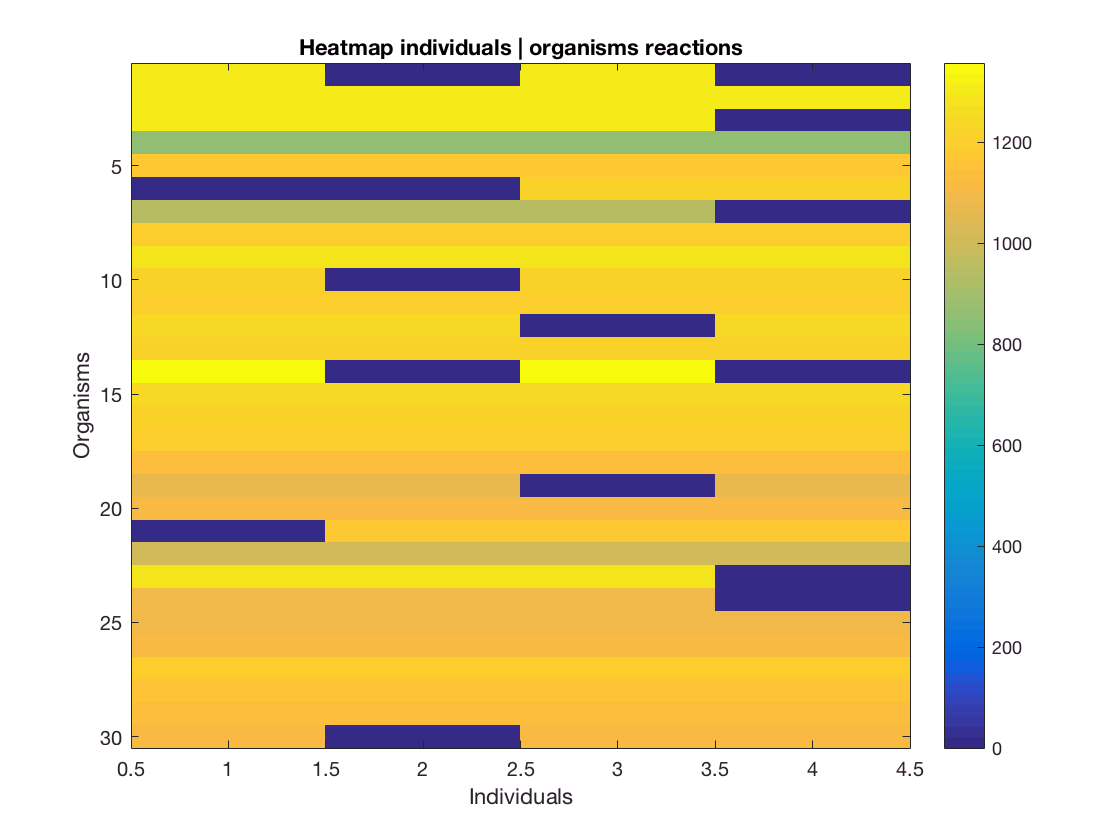

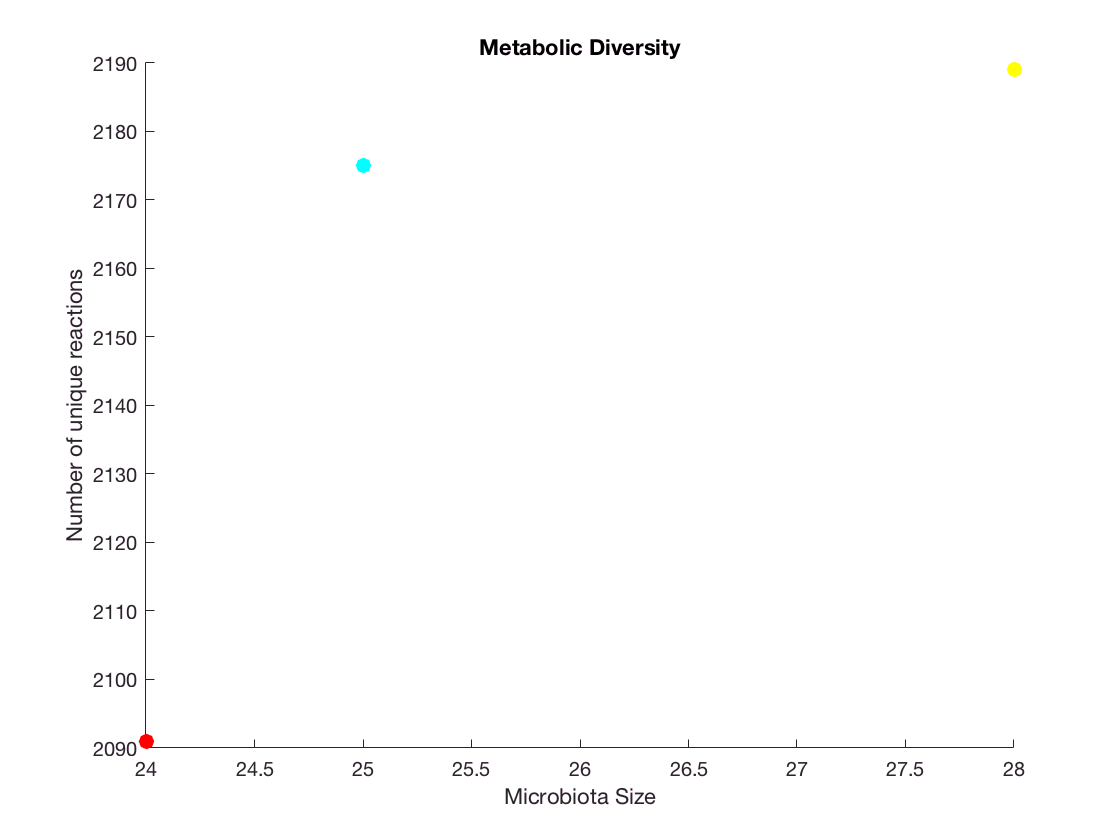

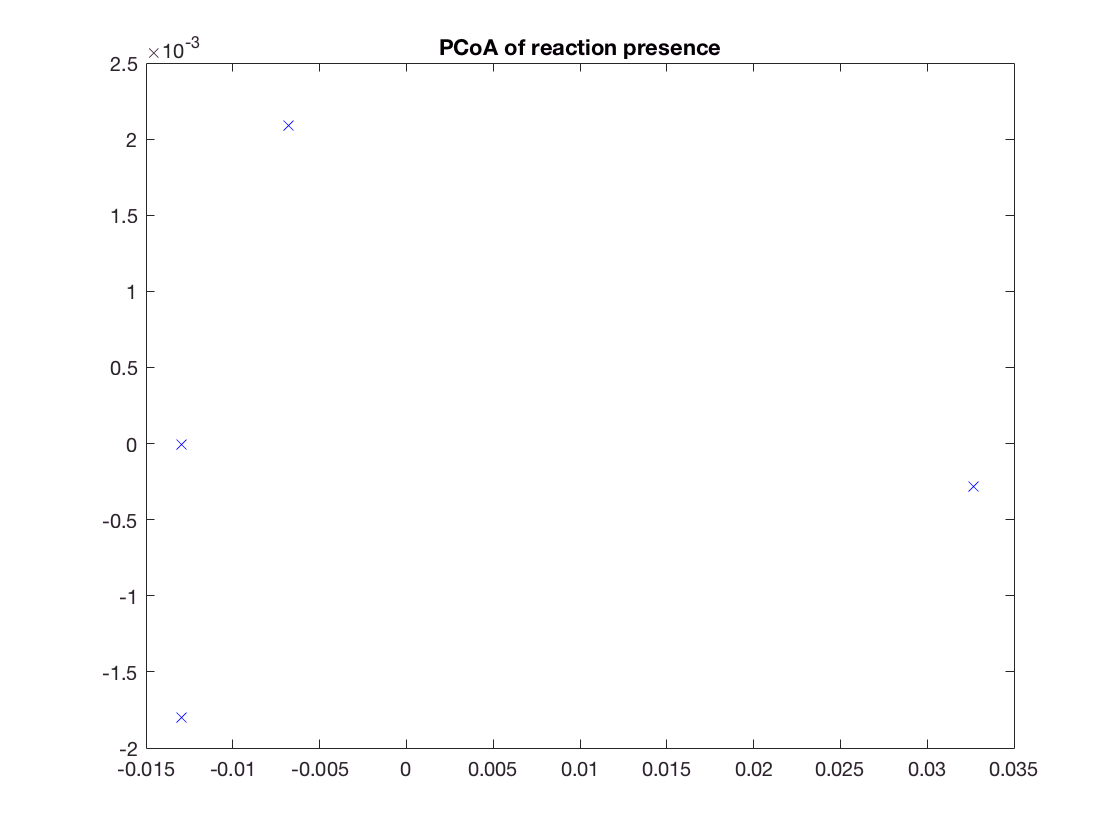

if isempty(mapP)
% Loading models 
models=loadUncModels(modPath,strains,objre);
% Computing genetic information
[reac,micRea,binOrg,patOrg,reacPat,reacNumb,reacSet,reacTab,reacAbun,reacNumber]=getMappingInfo(models,abunFilePath,patNumb)
writetable(cell2table(reacAbun),strcat(resPath,'reactions.csv'))

% Plotting genetic information
[PCoA]=plotMappingInfo(resPath,patOrg,reacPat,reacTab,reacNumber,patStat,figForm) 

if compMod==1
   mkdir(strcat(resPath,'compfile'))
   csvwrite(strcat(resPath,'compfile/reacTab.csv'),reacTab)
   writetable(cell2table(reacSet),strcat(resPath,'compfile/reacset.csv'))
   csvwrite(strcat(resPath,'compfile/reacNumb.csv'),reacNumb)
   csvwrite(strcat(resPath,'compfile/ReacPat.csv'),reacPat)
   csvwrite(strcat(resPath,'compfile/PCoA_tab.csv'),Y)
end

%Save all the created variables
save(strcat(resPath,'mapInfo.mat'))
end

%end of trigger for Autoload

## PIPELINE: [PART 2.1]

Checking consistence of inputs: if autofix == 0 halts execution with error msg if inconsistences are detected, otherwise it really tries hard to fix the problem and continues execution when possible. 

[autoStat,fixVec,strains]=checkNomenConsist(strains,autoFix);

No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomenclature
No potential problems found in checking organisms nomen

Now we detect from the content of the results folder If PART2 was already computed: if the associated file is already present in the results folder its execution is skipped else its execution starts

[mapP]=detectOutput(resPath,'Setup_allbacs.mat');

if isempty(mapP)
    modbuild = 1;
else
    modbuild = 0;
    s= 'global setup file found: loading from resPath and skipping [PART2.1] analysis';
    disp(s)
end

global setup file found: loading from resPath and skipping [PART2.1] analysis


%end of trigger for Autoload

A ?global? model joining all the reconstructions contained in the model will be created in this section. This model will be later used, integrating abundances coming from the metagenomic sequencing, to derive the different microbiota models. The result of this section will be automatically saved in the results folder. 

if modbuild == 1
   setup=fastSetupCreator(models, strains, {})
   setup.name='Global reconstruction with lumen / fecal compartments no host'
   setup.recon=0
   save(strcat(resPath,'Setup_allbacs.mat'), 'setup')
end

if modbuild==0
load(strcat(resPath,'Setup_allbacs.mat')) 
end

## PIPELINE: [PART 2.2]

Now we will create the different microbiota models integrating the given abundances. Coupling constraints and personalized "cumulative biomass" objective functions are also added. Models that are already existent will not be recreated, and new microbiota models will be saved in the results folder. 

[createdModels]=createPersonalizedModel(abunFilePath,resPath,setup,sampName,strains,patNumb)

mgmodel =                       c: [36426×1 double]
              citations: {36426×1 cell}
               comments: {36426×1 cell}
       confidenceScores: {36426×1 cell}
              ecNumbers: {36426×1 cell}
                grRules: {36426×1 cell}
                     lb: [36426×1 double]
                    rev: [36426×1 double]
                  rules: {36426×1 cell}
              rxnKeggID: {36426×1 cell}
               rxnNames: {36426×1 cell}
                   rxns: {36426×1 cell}
             subSystems: {36426×1 cell}
                     ub: [36426×1 double]
    rxnConfidenceScores: [36426×1 double]
           rxnECNumbers: {36426×1 cell}
              rxnKEGGID: {36426×1 cell}
                      S: [32054×36426 double]
                      b: [32054×1 double]
             metCHEBIID: {32054×1 cell}
              metCharge: [32054×1 double]
            metFormulas: {32054×1 cell}
                metHMDB: {32054×1 cell}
         metInchiString: {32054×1 cell}
          

id =     'SRS011061'


createdModels =     []
    'SRS011061'


mapP = 8

microbiota model file found: skipping model creation for this sample


mgmodel =                       c: [36426×1 double]
              citations: {36426×1 cell}
               comments: {36426×1 cell}
       confidenceScores: {36426×1 cell}
              ecNumbers: {36426×1 cell}
                grRules: {36426×1 cell}
                     lb: [36426×1 double]
                    rev: [36426×1 double]
                  rules: {36426×1 cell}
              rxnKeggID: {36426×1 cell}
               rxnNames: {36426×1 cell}
                   rxns: {36426×1 cell}
             subSystems: {36426×1 cell}
                     ub: [36426×1 double]
    rxnConfidenceScores: [36426×1 double]
           rxnECNumbers: {36426×1 cell}
              rxnKEGGID: {36426×1 cell}
                      S: [32054×36426 double]
                      b: [32054×1 double]
             metCHEBIID: {32054×1 cell}
              metCharge: [32054×1 double]
            metFormulas: {32054×1 cell}
                metHMDB: {32054×1 cell}
         metInchiString: {32054×1 cell}
          

id =     'SRS012902'


createdModels =     []
    'SRS011061'
    'SRS012902'


mapP = 10

microbiota model file found: skipping model creation for this sample


mgmodel =                       c: [36426×1 double]
              citations: {36426×1 cell}
               comments: {36426×1 cell}
       confidenceScores: {36426×1 cell}
              ecNumbers: {36426×1 cell}
                grRules: {36426×1 cell}
                     lb: [36426×1 double]
                    rev: [36426×1 double]
                  rules: {36426×1 cell}
              rxnKeggID: {36426×1 cell}
               rxnNames: {36426×1 cell}
                   rxns: {36426×1 cell}
             subSystems: {36426×1 cell}
                     ub: [36426×1 double]
    rxnConfidenceScores: [36426×1 double]
           rxnECNumbers: {36426×1 cell}
              rxnKEGGID: {36426×1 cell}
                      S: [32054×36426 double]
                      b: [32054×1 double]
             metCHEBIID: {32054×1 cell}
              metCharge: [32054×1 double]
            metFormulas: {32054×1 cell}
                metHMDB: {32054×1 cell}
         metInchiString: {32054×1 cell}
          

id =     'SRS011134'


createdModels =     []
    'SRS011061'
    'SRS012902'
    'SRS011134'


mapP = 9

microbiota model file found: skipping model creation for this sample


mgmodel =                       c: [36426×1 double]
              citations: {36426×1 cell}
               comments: {36426×1 cell}
       confidenceScores: {36426×1 cell}
              ecNumbers: {36426×1 cell}
                grRules: {36426×1 cell}
                     lb: [36426×1 double]
                    rev: [36426×1 double]
                  rules: {36426×1 cell}
              rxnKeggID: {36426×1 cell}
               rxnNames: {36426×1 cell}
                   rxns: {36426×1 cell}
             subSystems: {36426×1 cell}
                     ub: [36426×1 double]
    rxnConfidenceScores: [36426×1 double]
           rxnECNumbers: {36426×1 cell}
              rxnKEGGID: {36426×1 cell}
                      S: [32054×36426 double]
                      b: [32054×1 double]
             metCHEBIID: {32054×1 cell}
              metCharge: [32054×1 double]
            metFormulas: {32054×1 cell}
                metHMDB: {32054×1 cell}
         metInchiString: {32054×1 cell}
          

id =     'SRS054956'


createdModels =     []
    'SRS011061'
    'SRS012902'
    'SRS011134'
    'SRS054956'


mapP = 11

microbiota model file found: skipping model creation for this sample


createdModels =     []
    'SRS011061'
    'SRS012902'
    'SRS011134'
    'SRS054956'


## PIPELINE: [PART 3]

Add some description of what the computed outputs are and what is located in which file-Almut

In this phase, for each microbiota model, a diet, in the form of set constraints to the exchanges reactions of the diet compartment, is integrated. Flux Variability analysis for all the exchange reactions of the diet and fecal compartment is also computed and saved. 

[ID,fvaCt,nsCt,presol,inFesMat]=microbiotaModelSimulator(resPath,setup,sampName,dietFilePath,rDiet,0,extSolve,patNumb,fvaType)

mapP = 397

simulations already done, file found: loading from resPath


ID =     'EX_12dgr180[fe]'
    'EX_12ppd_S[fe]'
    'EX_26dap_M[fe]'
    'EX_2hyoxplac[fe]'
    'EX_2obut[fe]'
    'EX_2omfuc[fe]'
    'EX_2omxyl[fe]'
    'EX_3ddlhept[fe]'
    'EX_3mop[fe]'
    'EX_4hbz[fe]'
    'EX_7dhcdchol[fe]'
    'EX_7ocholate[fe]'
    'EX_C02528[fe]'
    'EX_Lcyst[fe]'
    'EX_Lcystin[fe]'
    'EX_Ser_Thr[fe]'
    'EX_T_antigen[fe]'
    'EX_Tn_antigen[fe]'
    'EX_Tyr_ggn[fe]'
    'EX_ac[fe]'
    'EX_acald[fe]'
    'EX_acerA[fe]'
    'EX_acgal[fe]'
    'EX_acgalglcur[fe]'
    'EX_acgalidour2s[fe]'
    'EX_acgalidour[fe]'
    'EX_acgam[fe]'
    'EX_acmana[fe]'
    'EX_acnam[fe]'
    'EX_ade[fe]'
    'EX_adn[fe]'
    'EX_adocbl[fe]'
    'EX_ala_L[fe]'
    'EX_alaasp[fe]'
    'EX_alagln[fe]'
    'EX_alaglu[fe]'
    'EX_alagly[fe]'
    'EX_alahis[fe]'
    'EX_alaleu[fe]'
    'EX_alathr[fe]'
    'EX_amp[fe]'
    'EX_amylopect900[fe]'
    'EX_amylose300[fe]'
    'EX_apio_D[fe]'
    'EX_arab_L[fe]'
    'EX_arabinan101[fe]'
    'EX_arabinogal[fe]'
    'EX_arabinoxyl[fe]

fvaCt =               []              []              []              []
    {307×3 cell}    {307×3 cell}    {307×3 cell}    {307×3 cell}
              []              []              []              []


nsCt =               []              []              []              []
    {307×3 cell}    {307×3 cell}    {307×3 cell}    {307×3 cell}
              []              []              []              []


presol =      []          []
    [1]    [0.3601]
    [1]    [0.2902]
    [1]    [0.3725]
    [1]    [0.3844]



inFesMat =

  0×0 empty cell array



Finally, NMPCs (net maximal production capability) are computed in a metabolite resolved manner and saved in a comma delimited file in the results folder. NMPCs indicate the maximal production of each metabolite and are computing summing the maximal secretion flux with the maximal uptake flux. Similarity of metabolic profiles (using the different NMPCs as features) between individuals are also evaluated with classical multidimensional scaling. 

init = 2

fl = 2

names =     'rich'    'standard'    'personalized'


noPcoa = 0

noPcoa = 0

noPcoa = 0

noPcoa = 0

P =    1.0e+04 *

    2.9570    0.0001
    1.9523    0.0001
    0.7309    0.0000
   -0.0000   -0.0000


Fsp =          0         0         0         0
         0         0         0         0
   44.8687   35.5302   11.6037    0.9619
         0         0         0         0
   93.3584   77.7395   48.7473   78.4956
         0         0         0         0
         0         0         0         0
         0         0         0         0
    2.2933    0.0144   28.2133    6.7012
    0.0001    0.0000    0.0003    0.0000


Y =   -98.6158  -70.4971  -34.8909
  -63.6848   48.9105   59.8644
  117.3366  -66.4325   20.6509
   44.9640   88.0191  -45.6243


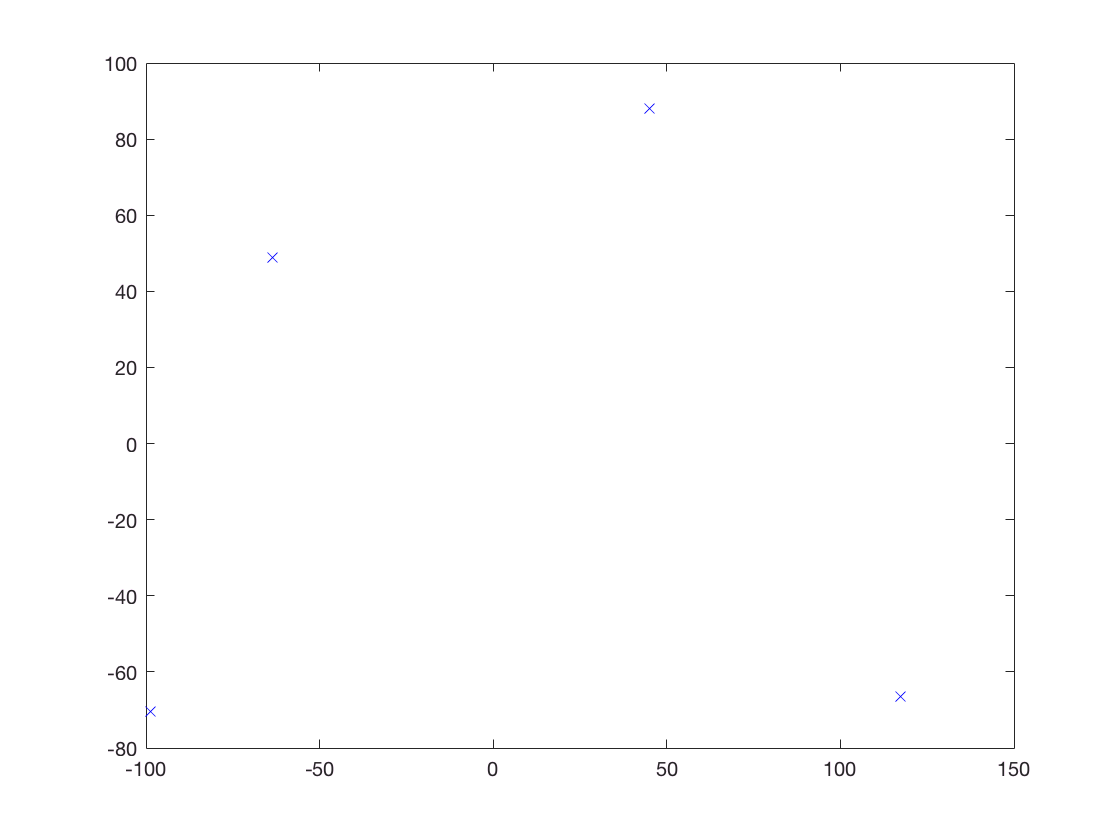

[Fsp,Y]= mgSimResCollect(resPath,ID,rDiet,0,patNumb,fvaCt,figForm)